# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet
% c1 = 0.0010;  
% c2 = 0.0196;
c1 = 0.0010;  
c2 = 0.0196;

c3 = 0.0013;
c4 = 0.0108;

tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 7.5;
x1 = 10;
xO0 = 5;
aa=-5;
bb=5;
cc=1;

**Target Shape **`h_target`

a=round(aa/dx+N/2);
b=round(bb/dx+N/2);
c=cc*ones(size(X));

h_region = ones(size(X));
h_region(1:a) = c(1:a) + tanh((X(1:a)-aa)./(2*x0));
h_region(a+1:(a+b)/2) = c(a+1:(a+b)/2) + tanh((X(a+1:(a+b)/2)-aa)./(.5*x0));
h_region((a+b)/2+1:b) = c((a+b)/2+1:b) - tanh((X((a+b)/2+1:b)-bb)./(.5*x0));
h_region(b+1:end) = c(b+1:end) - tanh((X(b+1:end)-bb)./(2*x0));

target = [a,b,h_region];

## **2) **

**Solutions**

Inside

[tSpan,D1,D2,X,H0,myObjective,conds_Sol,...
    fval,exitflag,output,history,History,h_Sol,H_Sol]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          82.6336         
     1            4          81.9239         initial simplex
     2            6          77.6513         expand
     3            8          69.0236         expand
     4           10          63.2394         expand
     5           12          49.9178         expand
     6           14          36.3555         expand
     7           16          33.9853         reflect
     8           17          33.9853         reflect
     9           19          33.9853         contract outside
    10           24          33.9853         shrink
    11           25          33.9853         reflect
    12           27          32.6832         contract inside
    13           28          32.6832         reflect
    14           30          32.6832         contract inside
    15           32          32.6832         contract inside
    16           34          31.1945         expand
    17         


[~,~,~,~,H_1,~,conds_Sol_1,...
    ~,~,output_1,history_1,History_1,h_Sol_1,H_Sol_1]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          88.1281         
     1            4          86.5077         initial simplex
     2            6          84.3709         expand
     3            8          81.7076         expand
     4           10          76.0149         expand
     5           12          66.6981         expand
     6           14          48.1023         expand
     7           16           37.355         expand
     8           17           37.355         reflect
     9           18           37.355         reflect
    10           19           37.355         reflect
    11           20           37.355         reflect
    12           21           37.355         reflect
    13           26           37.355         shrink
    14           27           37.355         reflect
    15           29           37.355         contract inside
    16           34           37.355         shrink
    17           35           37.355     

var = [A;N;k;y0]; 
h = hFinalRegion(history(:,6)',X,var,D1,D2,tSpan);
H = deval(h,tfinal); 
h1 = hFinalRegion(history_1(:,6),X,var,D1,D2,tSpan);
H1 = deval(h1,tfinal);   

**Inside Figures**

Fig. 0

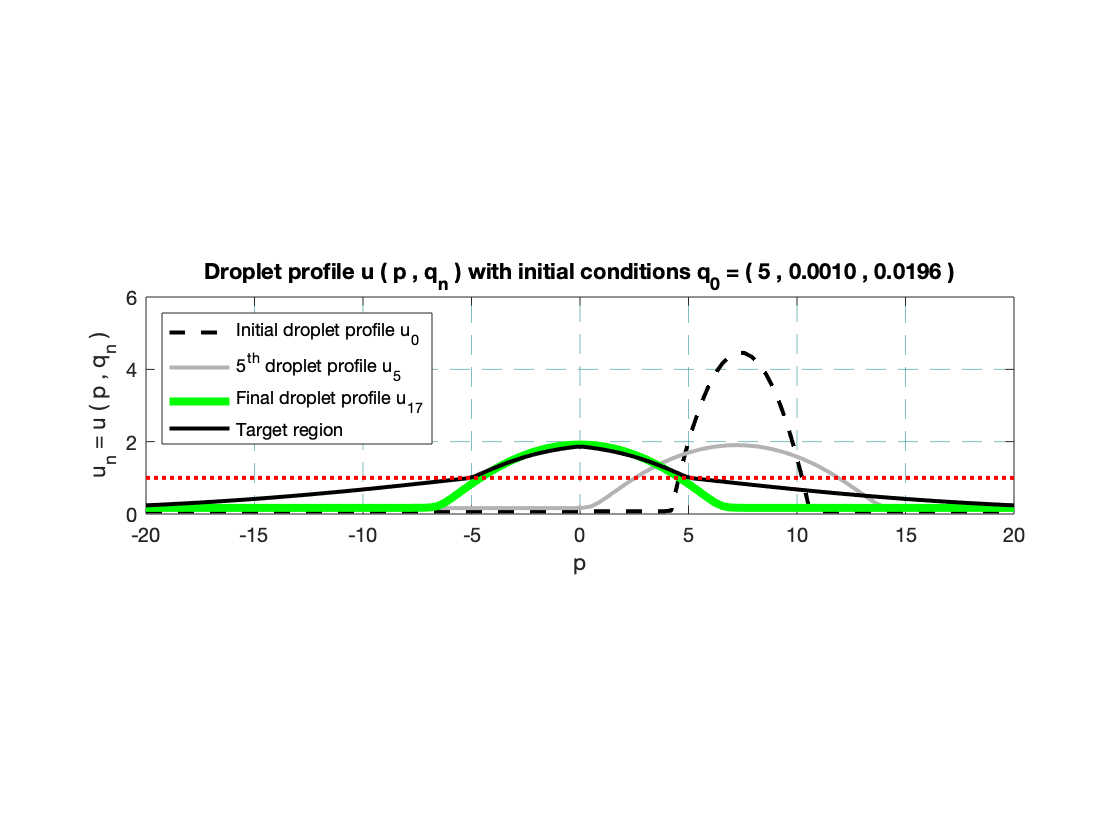

figure;
hold on
plot(X,H0,'k--','linewidth',2);
plot(X,H,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol,'g-','linewidth',4);
plot(X,h_region,'k-','linewidth',2);
plot(X,ones(size(X)),'r:','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    '5^{th} droplet profile u_{5}',...
    'Final droplet profile u_{17}',...
    'Target region',...
    'Location','northwest');
title('Droplet profile u ( p , q_n ) with initial conditions q_0 = ( 5 , 0.0010 , 0.0196 )');
hold off

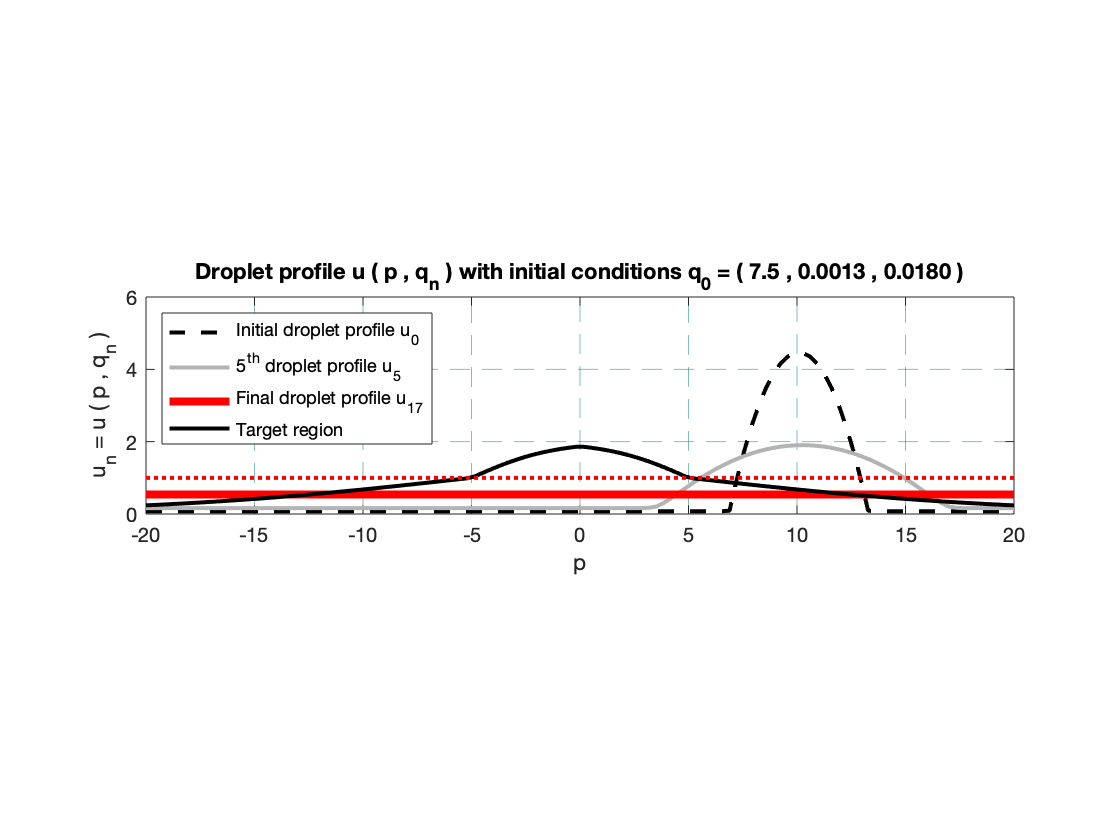


figure;
hold on
plot(X,H_1,'k--','linewidth',2);
plot(X,H1,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1,'r-','linewidth',4);
plot(X,h_region,'k-','linewidth',2);
plot(X,ones(size(X)),'r:','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    '5^{th} droplet profile u_{5}',...
    'Final droplet profile u_{17}',...
    'Target region',...
    'Location','northwest');
title('Droplet profile u ( p , q_n ) with initial conditions q_0 = ( 7.5 , 0.0013 , 0.0180 )');
hold off

**Joint Figures**

Fig. 1

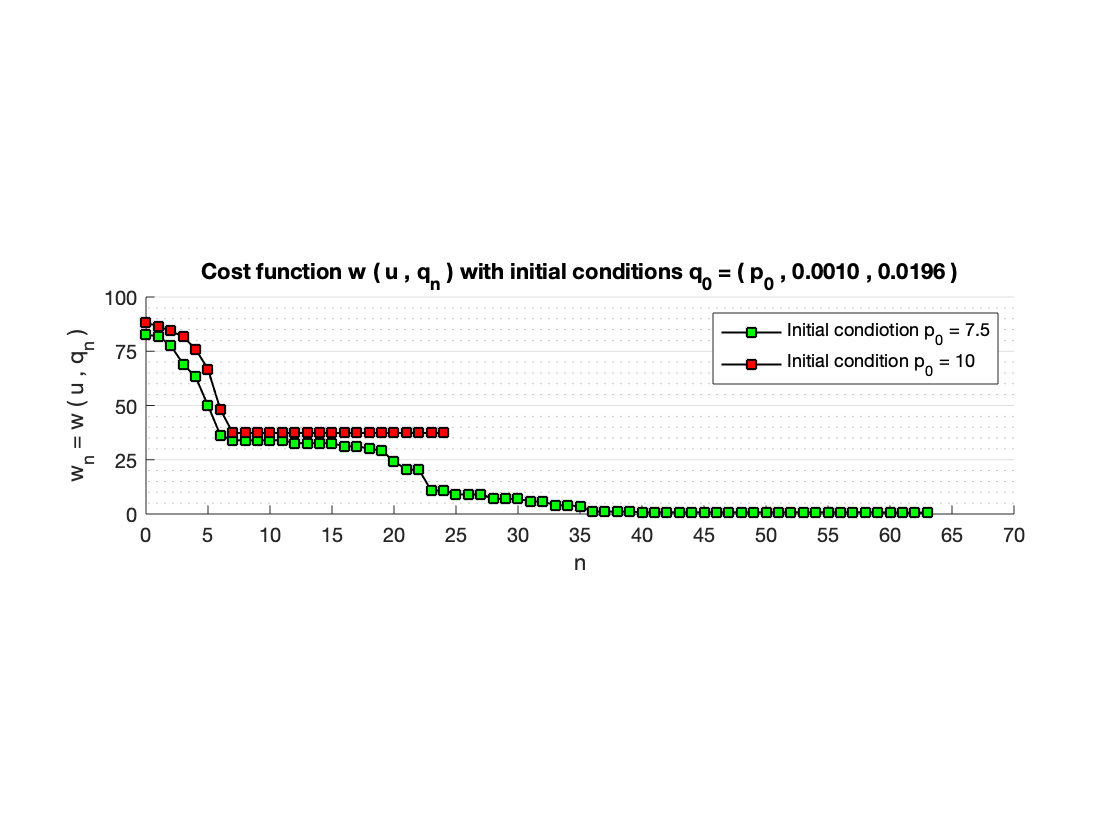

figure;
hold on
plot(0:63,History,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:24,History_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
ylabel('w_n = w ( u , q_n )');
xlabel('n');
legend('Initial condiotion p_0 = 7.5','Initial condition p_0 = 10','Location','northeast');
title('Cost function w ( u , q_n ) with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 70]);
ylim([0 100]);
set(gca,'xtick',0:5:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([4 1 1]);
box off
hold off

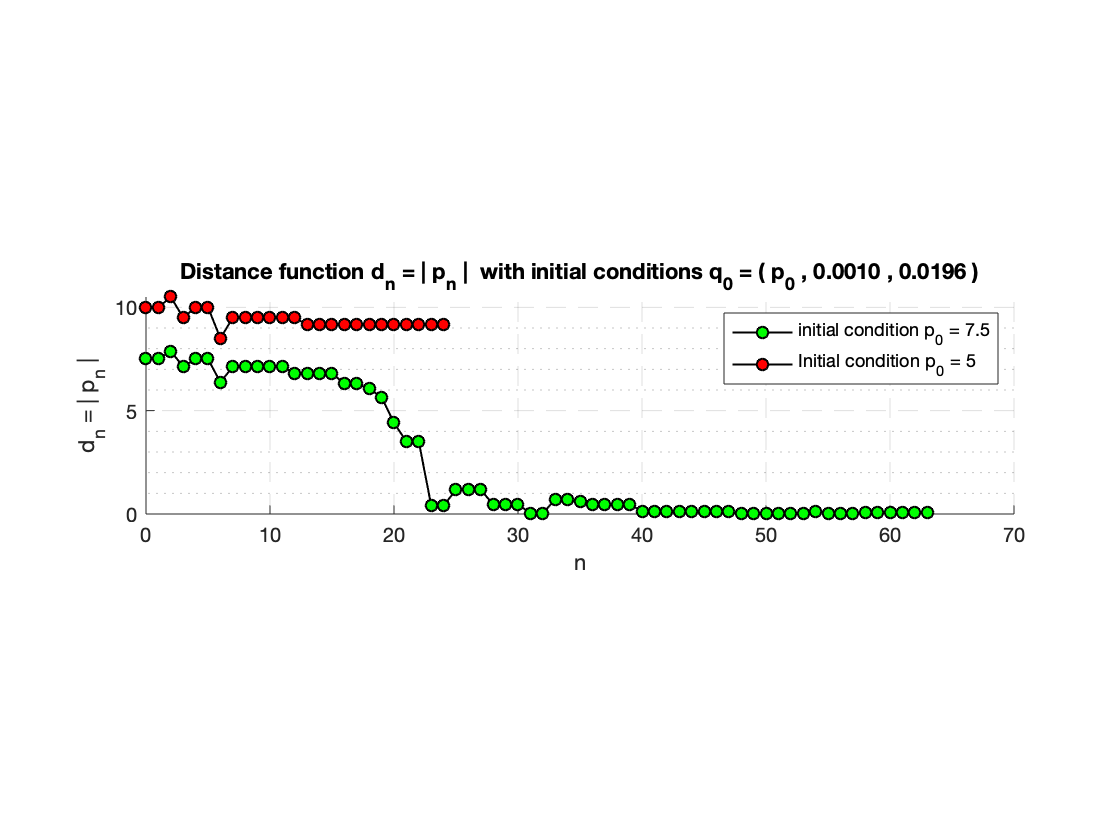


figure;
hold on
plot(0:63,abs(history(1,:)),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:24,abs(history_1(1,:)),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
ylabel('d_n = | p_n |');
xlabel('n');
legend('initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
title('Distance function d_n = | p_n |  with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 70]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.XAxisLocation = 'origin';
pbaspect([4 1 1]);
box off
hold off

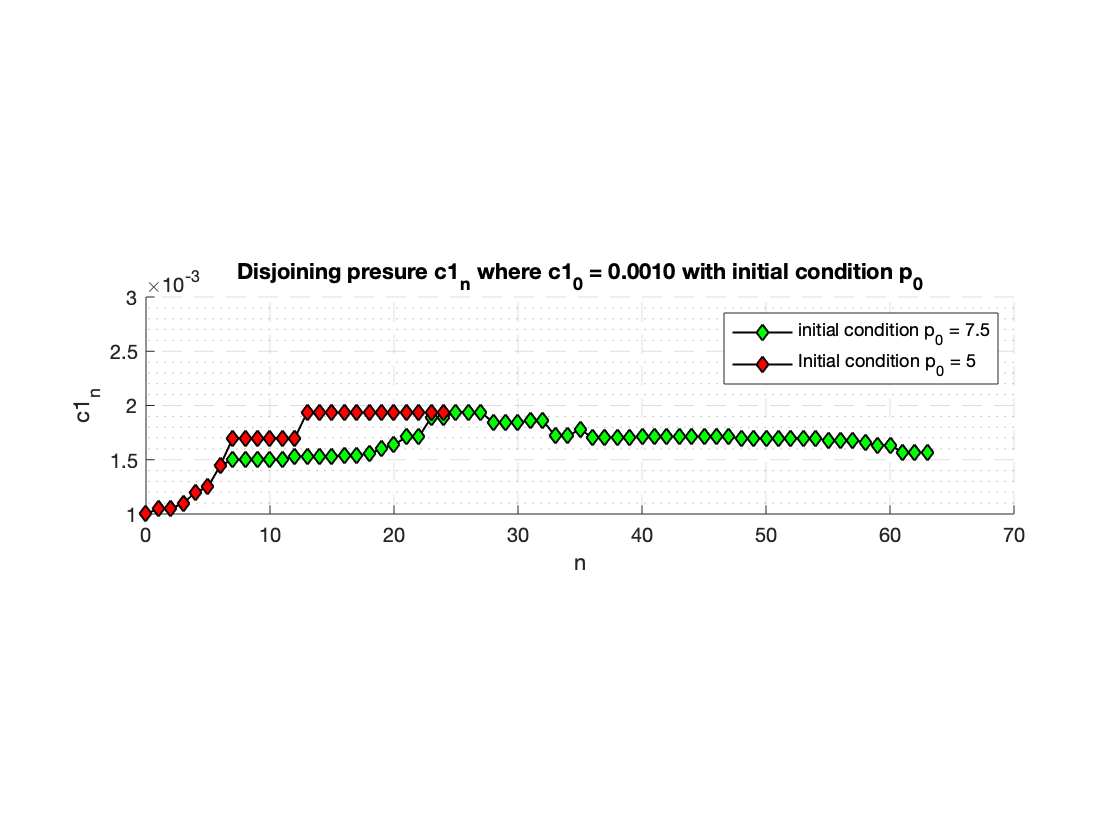



figure;
hold on
plot(0:63,history(2,:),'k-d',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:24,history_1(2,:),'k-d',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
pbaspect([4 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining presure c1_n where c1_0 = 0.0010 with initial condition p_0');
legend('initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
xlim([0 70]);
ylim([.001 .003]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

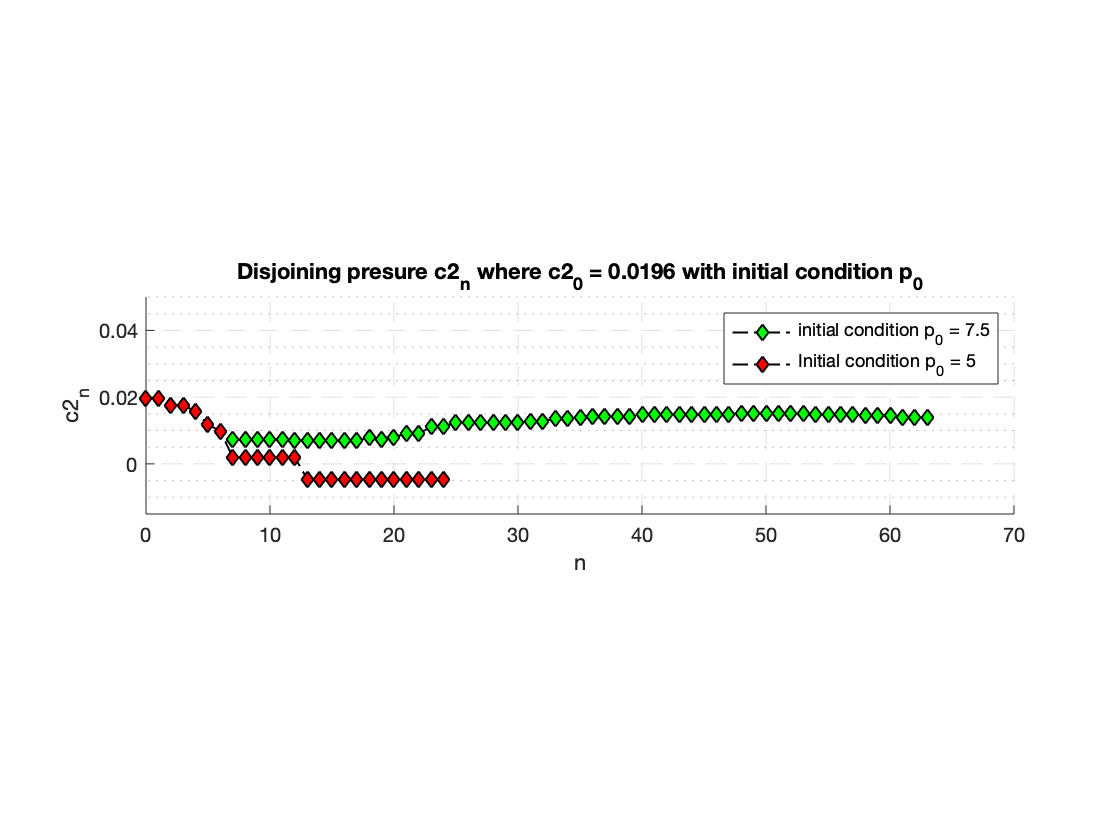



figure;
hold on
plot(0:63,history(3,:),'k-.d',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:24,history_1(3,:),'k-.d',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
pbaspect([4 1 1]);
ylabel('c2_n');
xlabel('n');
title('Disjoining presure c2_n where c2_0 = 0.0196 with initial condition p_0');
legend('initial condition p_0 = 7.5','Initial condition p_0 = 5','Location','northeast');
set(gca,'xtick',0:10:100);
xlim([0 70]);
ylim([-.015 .05]);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off